## Part 1

### Figure 1

Basic M-K plot

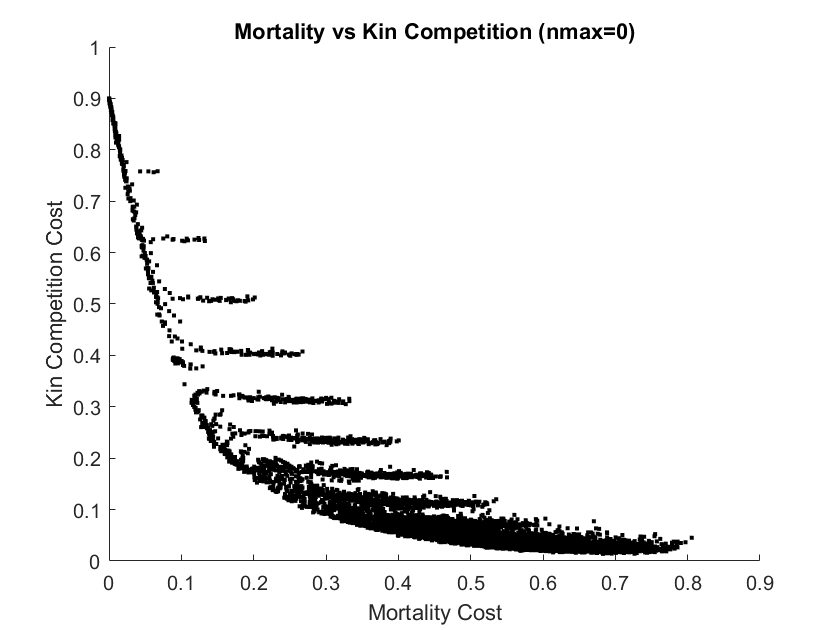

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

figure
hold on
plot(out_mortcost,out_kincost,'k.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=0)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\1.jpg')

### Figure 2

M-K plot with a couple of points highlighted, and the kernels at those points

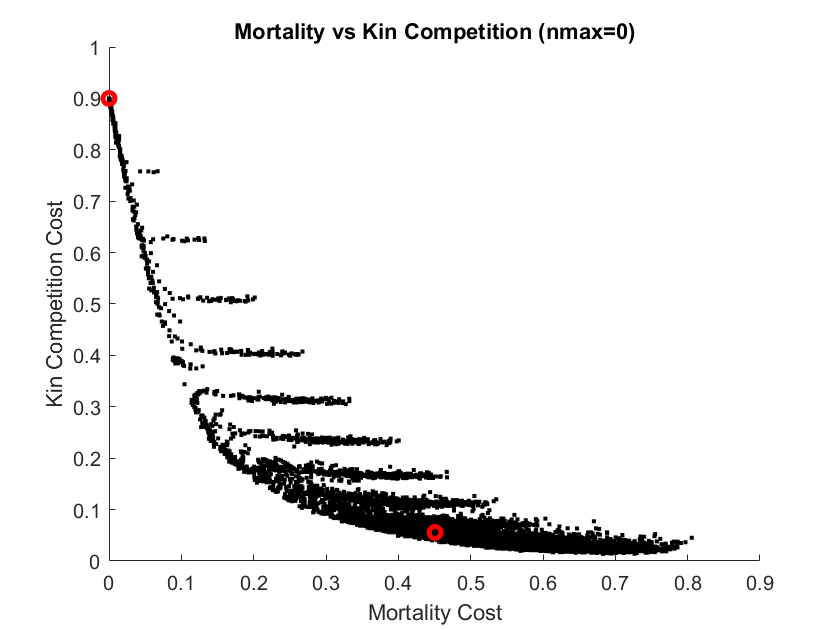

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

pts = [3000 6188]; %indices of points to emphasize, and plot kernels for

%2a
figure
hold on
plot(out_mortcost,out_kincost,'k.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')
plot(out_mortcost(pts),out_kincost(pts),'or','LineWidth',2.5)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=0)')
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\2a.jpg')

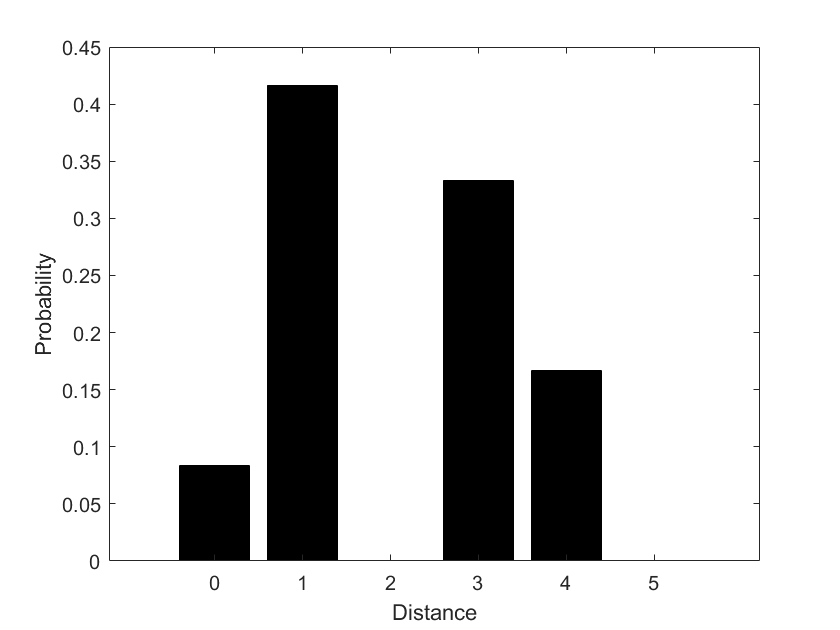


%2b,c
figure
bar(0:5,kernels(pts(1),:),'black')
xlabel('Distance')
ylabel('Probability')
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\2b.jpg')

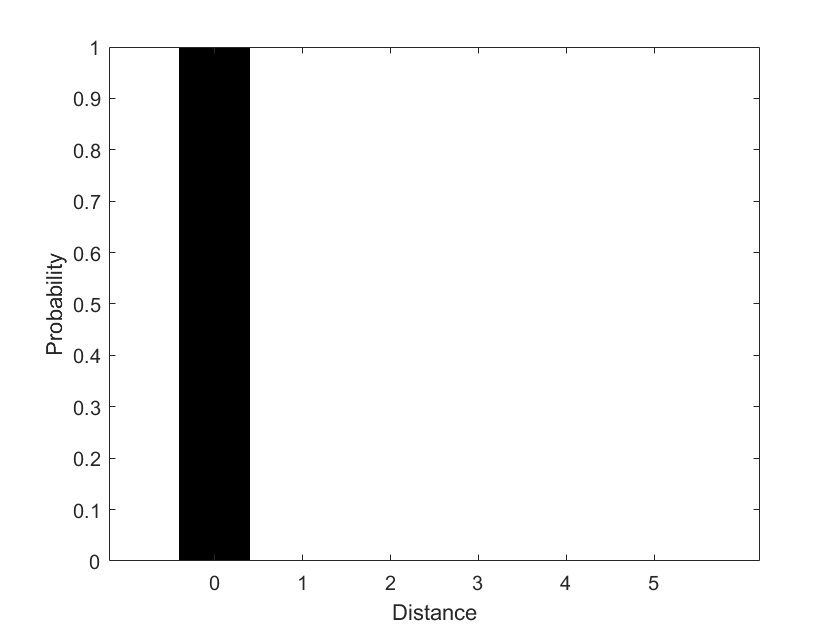


figure
bar(0:5,kernels(pts(2),:),'black')
xlabel('Distance')
ylabel('Probability')
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\2c.jpg')

### Figure 3

M-K plot, with fitness colors and boundary line added

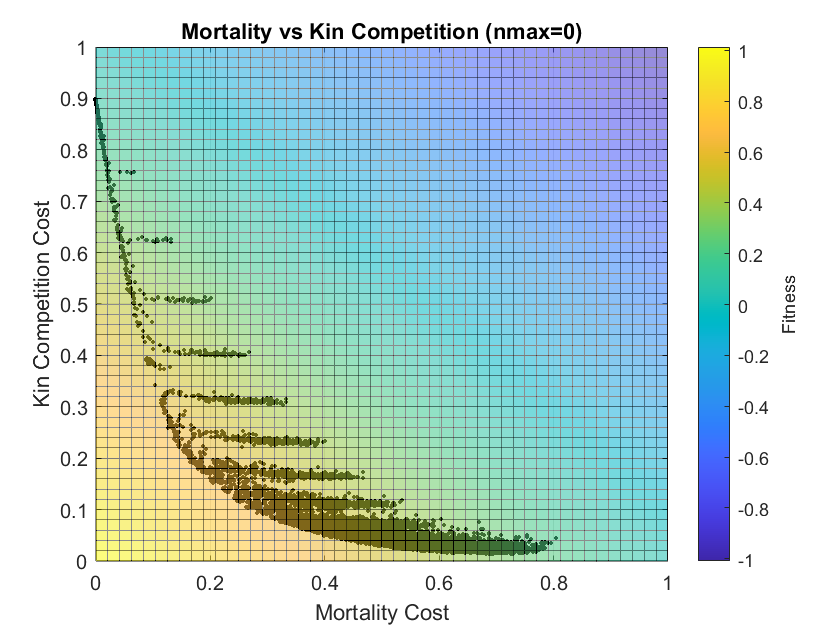

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on
fp = plot(f);
view(2)
set(fp,'FaceAlpha',0.55)
set(fp,'EdgeAlpha',0.45)
plot(out_mortcost,out_kincost,'k.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')
a = colorbar;
a.Label.String = 'Fitness';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=0)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\3.jpg')

### Figure 4

Fitness colors and boundary line only

### Figure 5

Fitness colors, boundary line, and trajectories

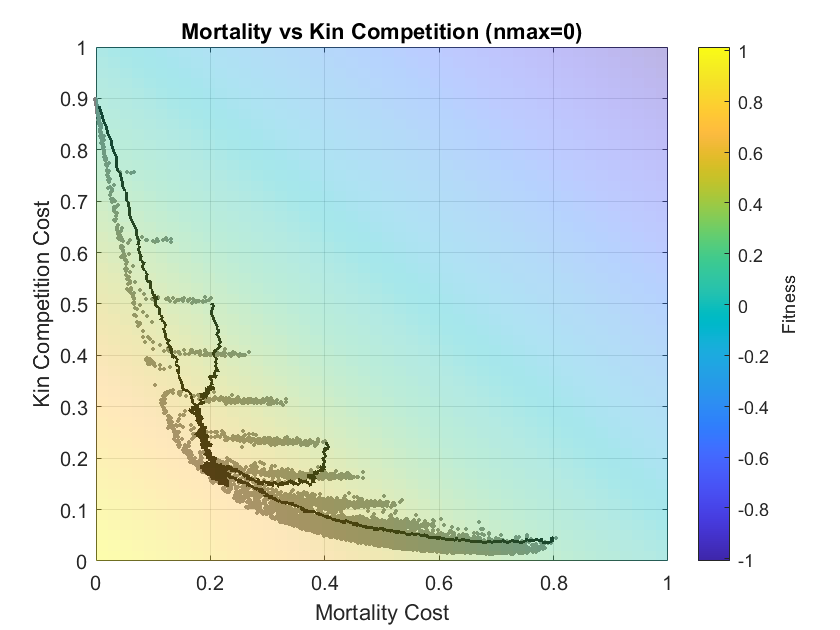

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
set(fp,'FaceAlpha',0.35)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'.','Color',[.5 .5 .5])
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'.','Color',[.5 .5 .5])

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

a = colorbar;
a.Label.String = 'Fitness';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=0)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\5.jpg')

### Figure 6

Fitness over time (plus kernel over time?)

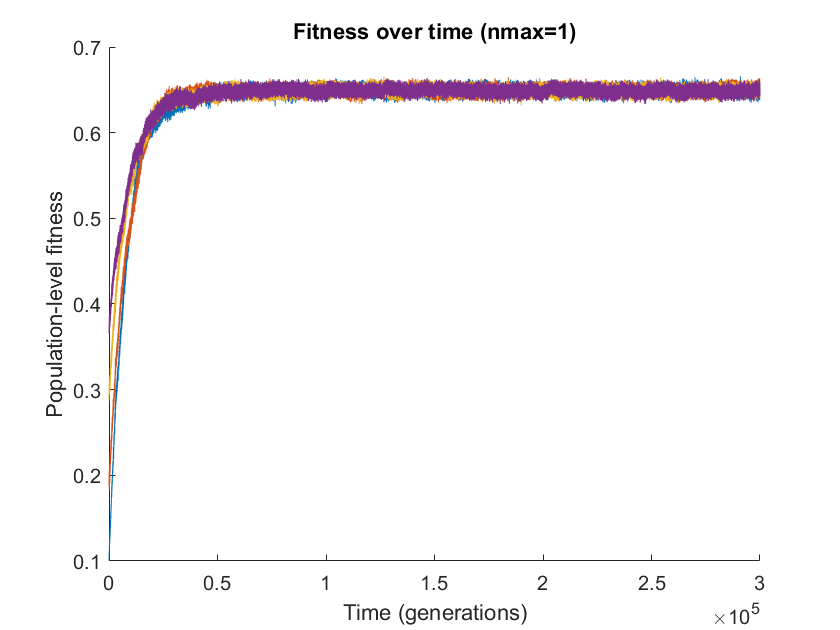

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;
fit_tl = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
dtime_br = dtime_avg;
fit_br = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
dtime_ae = dtime_avg;
fit_ae = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
dtime_re = dtime_avg;
fit_re = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');

figure
clf
hold on
plot(fit_tl)
plot(fit_br)
plot(fit_ae)
plot(fit_re)
xlabel('Time (generations)')
ylabel('Population-level fitness')
title('Fitness over time (nmax=1)')
hold off
%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\6a.jpg')

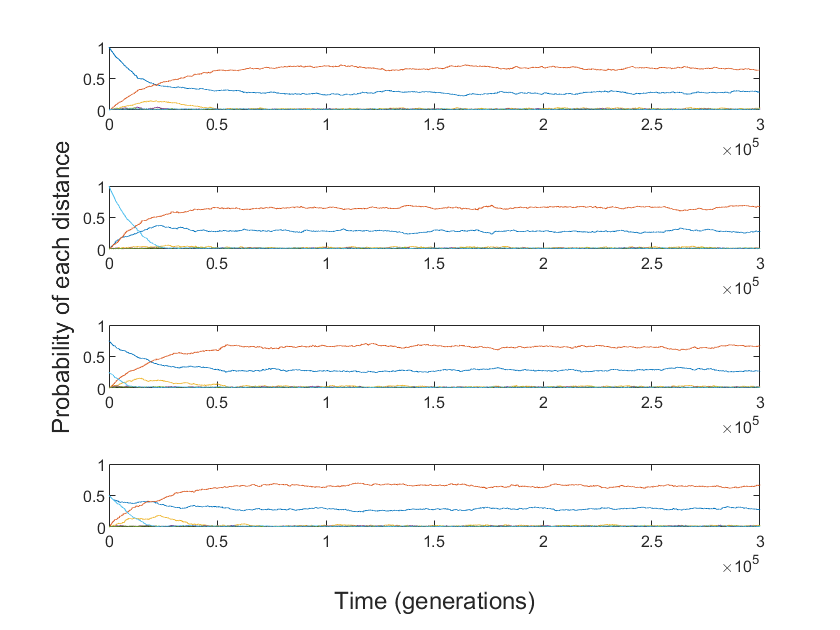


figure
clf
t = tiledlayout(4,1);
xlabel(t,'Time (generations)')
ylabel(t,'Probability of each distance')

nexttile
plot(dtime_tl)
ylim([0 1])

nexttile
plot(dtime_br)
ylim([0 1])

nexttile
plot(dtime_ae)
ylim([0 1])

nexttile
plot(dtime_re)
ylim([0 1])

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\6b.jpg')

### Figure 7

ESS kernel (w/variance)

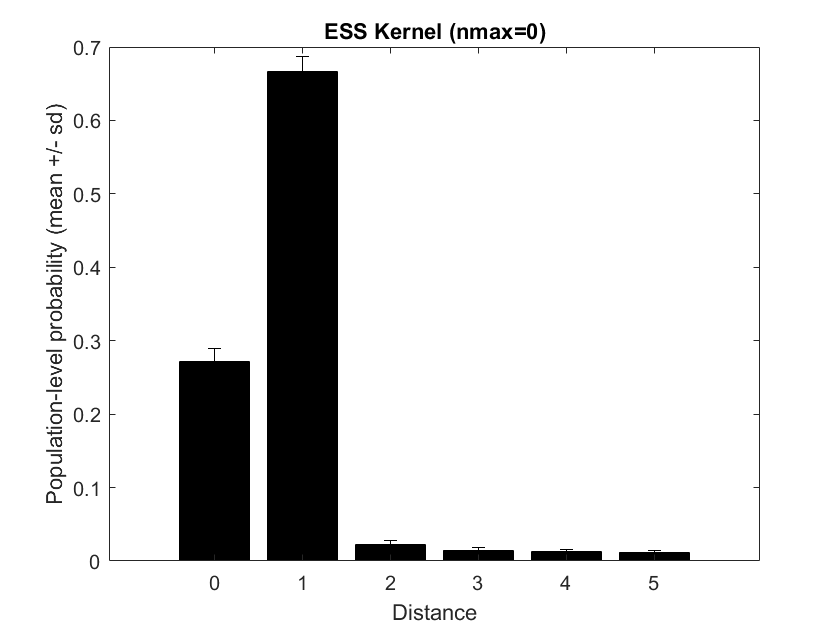

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;

ESS_mean_tl = mean(dtime_tl(100000:300000,:));
ESS_std_tl = std(dtime_tl(100000:300000,:));

figure
bar(0:5,ESS_mean_tl,'k')
hold on
er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Population-level probability (mean +/- sd)')
title('ESS Kernel (nmax=0)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\7.jpg')



%% they're all the same, so let's just do one
% ESS_mean_br = mean(dtime_br(100000:300000,:));
% ESS_std_br = std(dtime_br(100000:300000,:));
% 
% ESS_mean_ae = mean(dtime_ae(100000:300000,:));
% ESS_std_ae = std(dtime_ae(100000:300000,:));
% 
% ESS_mean_re = mean(dtime_re(100000:300000,:));
% ESS_std_re = std(dtime_re(100000:300000,:));

% tiledlayout(2,2)
% 
% nexttile
% bar(0:5,ESS_mean_tl)
% hold on
% er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off
% 
% nexttile
% bar(0:5,ESS_mean_br)
% hold on
% er = errorbar(0:5,ESS_mean_br,ESS_std_br,ESS_std_br);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off
% 
% nexttile
% bar(0:5,ESS_mean_ae)
% hold on
% er = errorbar(0:5,ESS_mean_ae,ESS_std_ae,ESS_std_ae);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off
% 
% nexttile
% bar(0:5,ESS_mean_re)
% hold on
% er = errorbar(0:5,ESS_mean_re,ESS_std_re,ESS_std_re);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off


## Part 2

### Figure 8

Fitness colors, boundary line (or points?), and trajectories for nmax=1,2

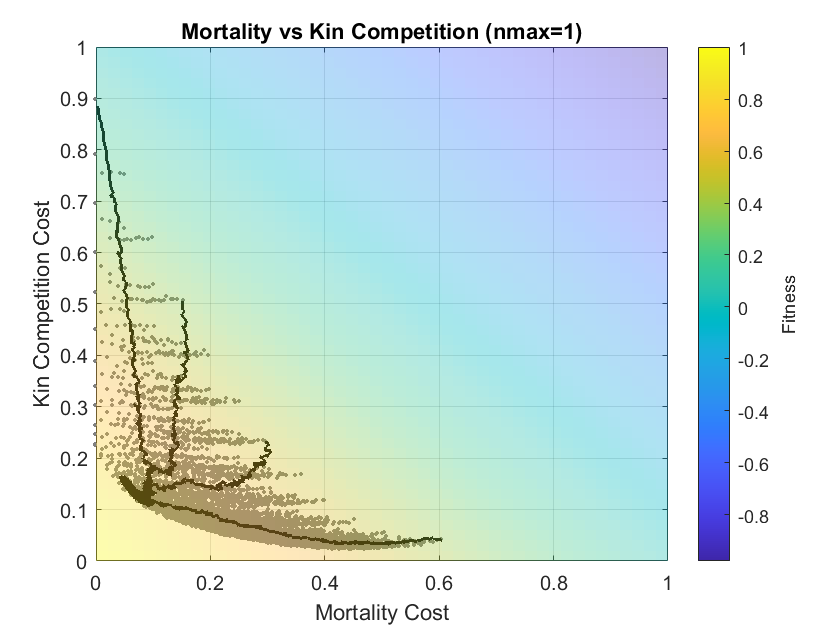

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_1\fitness_surface_lg.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
set(fp,'FaceAlpha',0.35)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'.','Color',[.5 .5 .5])

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

a = colorbar;
a.Label.String = 'Fitness';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=1)')
hold off

saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\8a.jpg')

nmax=2

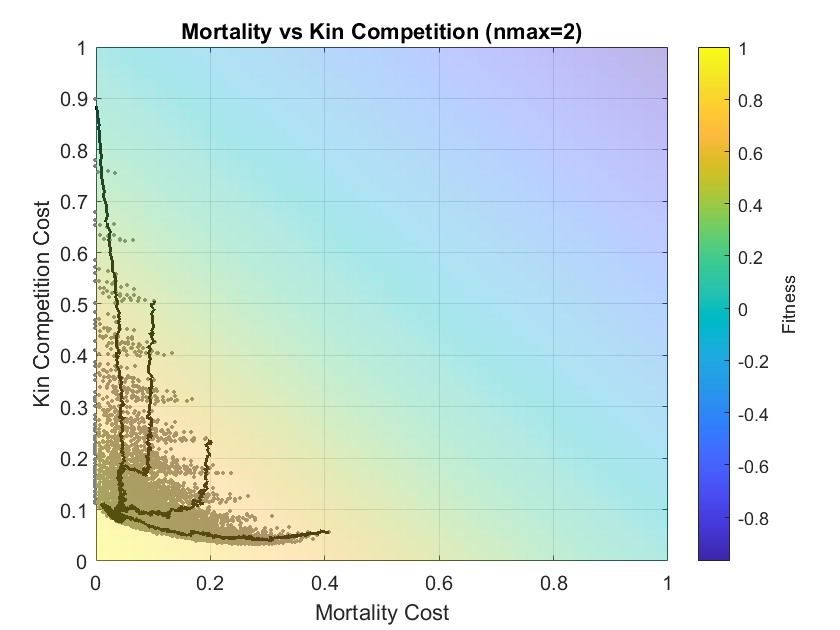

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_2\fitness_surface_lg.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
set(fp,'FaceAlpha',0.35)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'.','Color',[.5 .5 .5])

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

a = colorbar;
a.Label.String = 'Fitness';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=2)')
hold off

saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\8b.jpg')

### Figure 9

Fitness over time, nmax=1,2

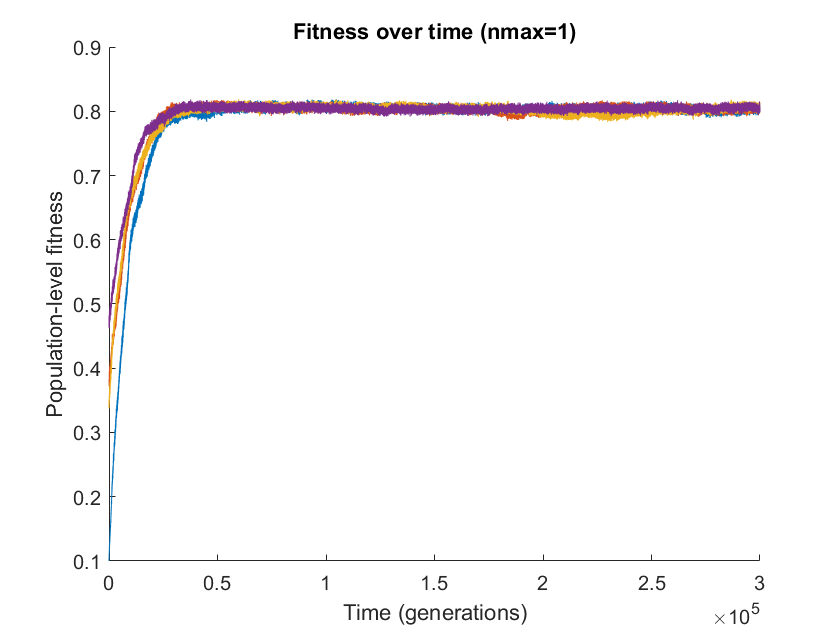

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;
fit_tl = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_br = dtime_avg;
fit_br = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_ae = dtime_avg;
fit_ae = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_re = dtime_avg;
fit_re = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');

figure
clf
hold on
plot(fit_tl)
plot(fit_br)
plot(fit_ae)
plot(fit_re)
xlabel('Time (generations)')
ylabel('Population-level fitness')
title('Fitness over time (nmax=1)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\9a.jpg')

nmax=2

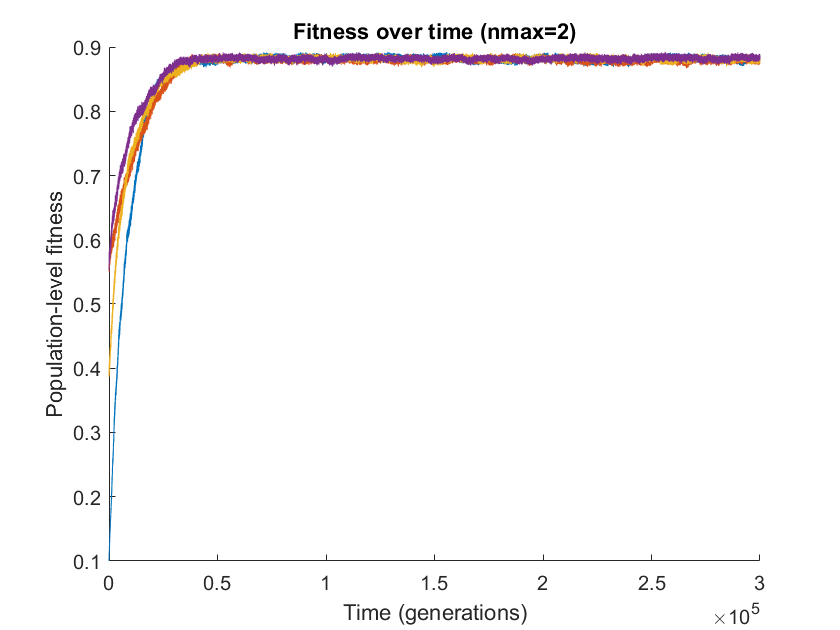

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;
fit_tl = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_br = dtime_avg;
fit_br = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_ae = dtime_avg;
fit_ae = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_re = dtime_avg;
fit_re = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');

figure
clf
hold on
plot(fit_tl)
plot(fit_br)
plot(fit_ae)
plot(fit_re)
xlabel('Time (generations)')
ylabel('Population-level fitness')
title('Fitness over time (nmax=2)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\9b.jpg')

### Figure 10

ESS kernels (w/variance), nmax=1,2

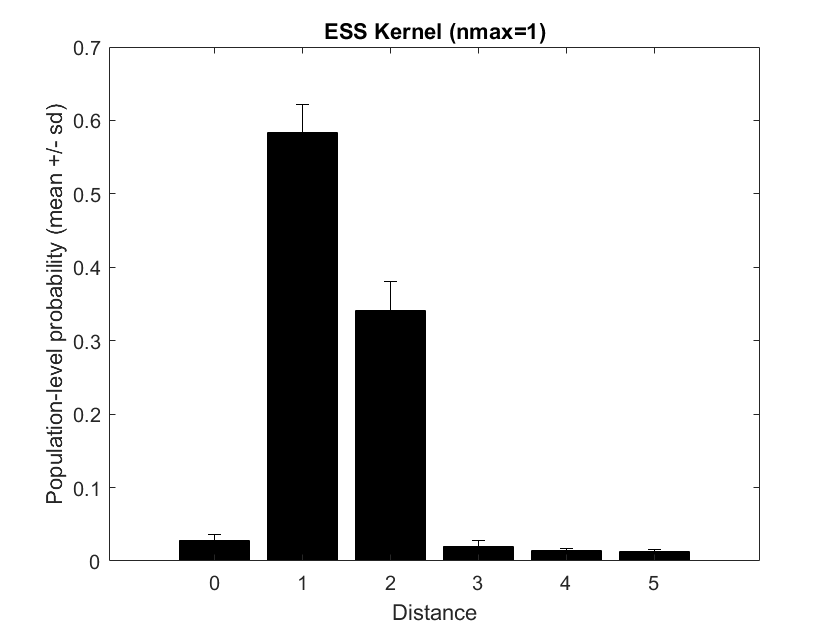

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;

ESS_mean_tl = mean(dtime_tl(100000:300000,:));
ESS_std_tl = std(dtime_tl(100000:300000,:));

figure
bar(0:5,ESS_mean_tl,'k')
hold on
er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Population-level probability (mean +/- sd)')
title('ESS Kernel (nmax=1)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\10a.jpg')

nmax=2

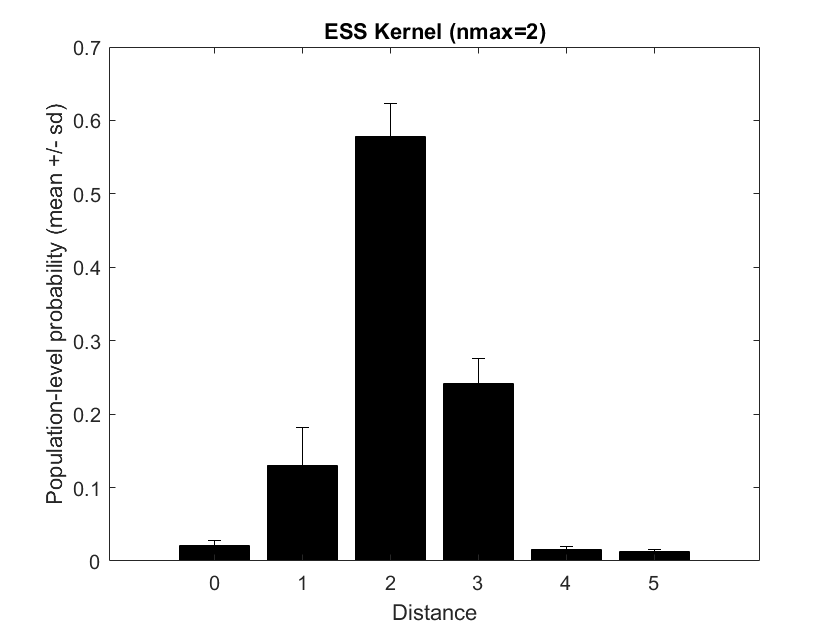

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;

ESS_mean_tl = mean(dtime_tl(100000:300000,:));
ESS_std_tl = std(dtime_tl(100000:300000,:));

figure
bar(0:5,ESS_mean_tl,'k')
hold on
er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Population-level probability (mean +/- sd)')
title('ESS Kernel (nmax=2)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\10b.jpg')